clearvars; close all; clc;
addpath ("hydraulicLosses\")
addpath ("Motor\")
addpath ("pumpFunctions\")
addpath ("pumps\")
addpath ("initialData\")
addpath ("imagenes\")
addpath (genpath("electricModel\"))

***Batería comercial con potencia constante e intensidad variable***

***Descarga***

# Battery properties

[experiment, electrolite, electrode, manifold, frame, nCell, nStack, SoCmax,SoCmin, pipe, comertialElements, limitPump, rto] = initValues();
battery = initBatt(nStack, nCell, SoCmax) % nStacks, nCell, z_ini -> initial SoC

battery = struct with fields:
           r0: 0.1080
           rn: 0
           rc: 0
            Q: 15000
        cells: 80
          ocv: [100×1 double]
          soc: [100×1 double]
       etaChg: 0.9500
        power: 12000
          z_k: 0.9000
          v_k: 115.0388
        irn_k: 0
    vHistoric: []
    zHistoric: []
    pHistoric: []
    eHistoric: []
    iHistoric: []


- z_ini - SoC

## Power to desire SoC simulation

[battery, t] = CP(battery, battery.power, 0.20) % Constant Power simulation % (battery, power, expectedSoC) 

battery = struct with fields:
           r0: 0.1080
           rn: 0
           rc: 0
            Q: 15000
        cells: 80
          ocv: [100×1 double]
          soc: [100×1 double]
       etaChg: 0.9500
        power: 12000
          z_k: 0.1998
          v_k: 88.0957
        irn_k: 136.2129
    vHistoric: [103.7730 102.5426 102.3846 102.3568 102.3450 102.3353 102.3260 102.3170 102.3079 102.2989 102.2898 102.2807 102.2717 102.2626 102.2536 102.2445 102.2355 102.2264 102.2173 102.2083 102.1992 102.1901 102.1811 102.1720 102.1629 102.1539 … ]
    zHistoric: [0.8998 0.8997 0.8995 0.8993 0.8992 0.8990 0.8988 0.8986 0.8985 0.8983 0.8981 0.8979 0.8978 0.8976 0.8974 0.8972 0.8971 0.8969 0.8967 0.8965 0.8964 0.8962 0.8960 0.8959 0.8957 0.8955 0.8953 0.8952 0.8950 0.8948 0.8946 0.8945 0.8943 … ]
    pHistoric: [-1.0825e+04 -1.1858e+04 -1.1982e+04 -1.1997e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1.1999e+04 -1

t = -23033010

Power - 7000? W? Depende del signo que le quieras dar ya que le dices que vaya de un valor de SoC a otro

expectedSoc - entiendo que va del 100 al 20% de SoC

# Current Density

**    Current density =  current [A] / A_electrode [cm^2]**

currentDensity = abs(battery.iHistoric*1000/ (electrode.We * electrode.Le * 10000));

tablaModeloElectrico.Potencia = battery.power;
tablaModeloElectrico.Capacidad = battery.Q;
tablaModeloElectrico.SoCMin = min(battery.zHistoric);
tablaModeloElectrico.SoCMax = max(battery.zHistoric);

tablaModeloElectrico.TensionMin = min(battery.vHistoric);
tablaModeloElectrico.TensionMax = battery.vHistoric(2);

tablaModeloElectrico.CorrienteMin = min(battery.iHistoric);
tablaModeloElectrico.CorrienteMax = battery.iHistoric(2);

tablaModeloElectrico.DensidadElectricaMin = currentDensity(2);
tablaModeloElectrico.DensidadElMax = max(currentDensity);
tablaModeloElectrico.Tiempo = length(currentDensity);
struct2table(tablaModeloElectrico)

ans = 1×11 table
    Potencia    Capacidad    SoCMin     SoCMax     TensionMin    TensionMax    CorrienteMin    CorrienteMax    DensidadElectricaMin    DensidadElMax    Tiempo
    ________    _________    _______    _______    __________    __________    ____________    ____________    ____________________    _____________    ______

     12000        15000      0.19984    0.89985      88.096        102.54        -136.21         -115.64              72.273              85.133         3717 


### Current Density/time

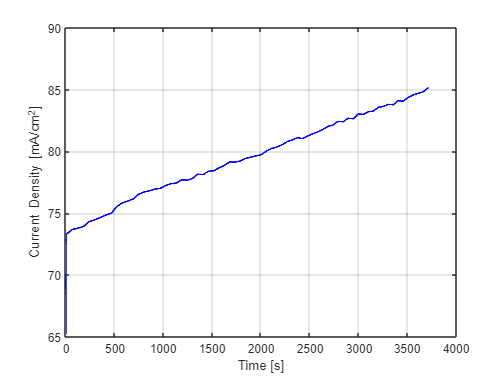

Density = figure();
plot(currentDensity, 'blue', 'LineWidth', 1.5)
ylabel('Current Density [mA/cm^2]')
grid on
%title('Current Density')
xlabel('Time [s]')

%changeFig(Density,'Current Density', 1)

***Current Density is required to be aproximatly 0.08 [A/cm^2]***

# Plots

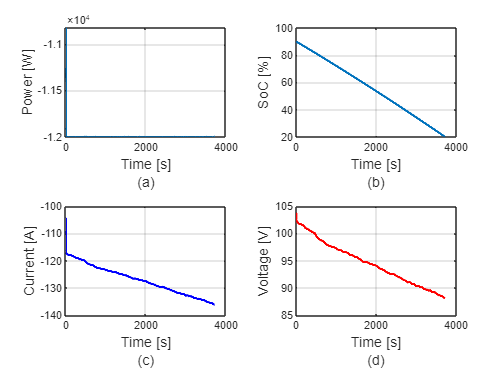

% Plot into first tile three times
figura = figure();

t = tiledlayout(2,2,'TileSpacing','Compact');
tiledlayout('flow')

nexttile
plot(battery.pHistoric, 'LineWidth', 2)
ylabel('Power [W]', 'FontSize',12)
grid on
%title('Battery power', 'FontSize',12)
xlabel({'Time [s]'; '(a)'}, 'FontSize',12)

% plot(currentDensity, 'blue', 'LineWidth', 1.5)
% ylabel('Current Density [mA/cm^2]','FontSize',12)
% grid on
% %title('Current Density')
% xlabel({'Time [s]'; '(a)'}, 'FontSize',12)


nexttile
plot(battery.zHistoric*100, 'LineWidth',2)
ylabel('SoC [%]', 'FontSize',12)
grid on
%title('Battery SoC', 'FontSize',12)
xlabel({'Time [s]'; '(b)'}, 'FontSize',12)

nexttile
plot(battery.iHistoric, 'blue', 'LineWidth', 2)
grid on
ylabel('Current [A]', 'FontSize',12)
%title('Battery current', 'FontSize',12)
xlabel({'Time [s]'; '(c)'}, 'FontSize',12)

nexttile
plot(battery.vHistoric, 'red', 'LineWidth', 2)
grid on
ylabel('Voltage [V]', 'FontSize',12)
%title('Battery terminal voltage', 'FontSize',12)
xlabel({'Time [s]'; '(d)'}, 'FontSize',12)

hold off

%changeFig(figura, 'Power Soc Current Voltage',4);

# Flow (l/min)

flow.cell = flowRequiredCellConstPower(battery.zHistoric,battery.iHistoric, electrolite.cv, experiment.FF); % (l/min)
flow.stack = flow.cell * nCell;     % (l/min)
flow.tot = nStack .* flow.stack;    % (l/min)

# Tank (liters)

TIME_h = floor(length(flow.cell)/3600);
TIME_s = length(flow.cell)/3600;
Energy_capacity = battery.power/TIME_s/1000 % kWh

Energy_capacity = 11.6223

mean(battery.vHistoric)

ans = 94.5306

mean(battery.vHistoric)/nCell/nStack

ans = 1.1816

LITERS = Energy_capacity*3600*1000 / (electrolite.cv*96485*(SoCmax - SoCmin)*mean(battery.vHistoric)/nStack/nCell)

LITERS = 317.7382

tablaFlow.QcellMin = min(flow.cell);
tablaFlow.QcellMax = max(flow.cell);
tablaFlow.QstackMin = min(flow.stack);
tablaFlow.QstackMax = max(flow.stack);
tablaFlow.QtotMin = min(flow.tot);
tablaFlow.QtotMax = max(flow.tot);
struct2table(tablaFlow)

ans = 1×6 table
    QcellMin    QcellMax    QstackMin    QstackMax    QtotMin    QtotMax
    ________    ________    _________    _________    _______    _______

    0.26214      1.5414      5.2427       30.827      20.971     123.31 


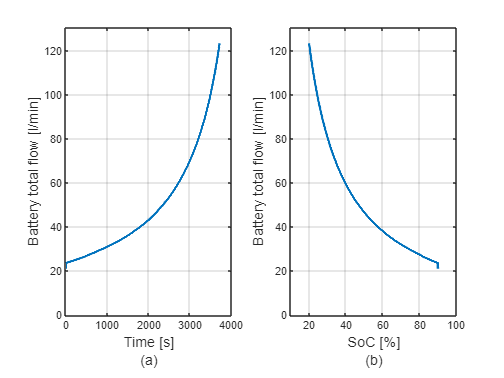

% Plot into first tile three times
flowPlot = figure();
tiledlayout(1,2,'TileSpacing','Compact');

nexttile(1)
plot(flow.tot, 'LineWidth', 2)
ylabel('Battery total flow [l/min]', 'FontSize',12)
grid on
%title('Battery flow', 'FontSize',12)
xlabel({'Time [s]'; '(a)'}, 'FontSize',12)
ylim([0 max(flow.tot)+7])

nexttile(2)
plot(battery.zHistoric.*100,flow.tot, 'LineWidth', 2)
ylabel('Battery total flow [l/min]', 'FontSize',12)
grid on
%title('Battery flow', 'FontSize',12)
xlabel({'SoC [%]'; '(b)'}, 'FontSize',12)
xlim([10 100])
ylim([0 max(flow.tot)+7])


%changeFig(flowPlot, 'Flow battery',2);

# Head (Pa)

##     Head in Stack (Pa)

format short
% Pressure drop in porous electrode
    head.Electrode = hElectrode(flow.cell, electrolite.mu, electrode.We, electrode.Le, electrode.He, electrode.df, electrode.ePorosity, electrode.cteCK); % Pa

% Head loss in frames
    % Simulation data for a specific design (losses in the ribs of the frame
    dataFrames = readmatrix("FrameLosses.xlsx");
    head.Frames = hFrames (dataFrames, flow.cell);
    clear dataFrames

% Pressure drop due to Manifold channel
    head.Manifold = hChannelRectangular(manifold.W, manifold.H, manifold.L, flow.stack, electrolite.rho, electrolite.mu, manifold.e); % Pa

% Gravity losses
    head.Gravity = 0;% hGravity(electrolite.rho, electrolite.g, manifold.hManifold,flow.stack); % Pa

% Minor losses
    head.MinorLossesStack = hMinorLossesStack(electrolite.rho, flow.cell, manifold.H, manifold.W, frame.HchannelBetweenRibs, frame.WchannelBetweenRibs,frame.numberOfHolesBetweenRibs); % Pa

% Total Stack
head.STACK = head.Electrode + 2.*head.Frames + 2.* head.Manifold + head.Gravity + head.MinorLossesStack; % Pa

    There are two manifolds, one for the flow input and another one for the flow output. It's the same for the channels of the frames, but in this case, this data of losses are collected in the excel call 'dataFrames'.

    Colectores de división de caudal: el paso de flujo de los manifold a los frames se van a considerar como perdidas por cambio brusco de sección en vez de considerarlos como un giro, ya que se va a suponer que el llenado del manifold es inmediato, e instantes después el flujo se reparte en los frames.

## Head in the hydraulic system

-  **Parallel losses:**

h_ab = h1 = h2 = ... = hn

It depends on the path and the flow rate. Linear losses and minor losses in the pipe system are taken into account.

- **    Linear losses**

hL =  f * L/D * rho * velocity ^2 / 2

To calculate linear losses is necessary to use the Colebrook equation, whose procedure is carried out thanks to the use of Matlab *fzero *function.

- **    Minor losses due to comertial elements such as valves, elbows, long radius, tees, etc.**

hMinor = k * rho * 1/2 * velocity ^2 = k * rho * 1/2 * (Q / Apiping) ^2

% LOSSES where flow is flow.stack
    head.pipe_stack = hPipe(pipe.diameter, pipe.LQ, pipe.epsilon, flow.stack, electrolite.rho, electrolite.mu); % Pa

K =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


    head.minor_stack = (2 * comertialElements.kValve + 2 * comertialElements.kLongRadius90 + 2 * comertialElements.kT) * electrolite.rho * 1/2 * (flow.stack / 1000 / 60) .^2 / (pipe.area ^ 2); % Pa

% LOSSES where flow is flow.tot
    head.pipe_tot = hPipe(pipe.diameter, pipe.L2Q, pipe.epsilon, flow.tot, electrolite.rho, electrolite.mu); % Pa

K =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


    head.minor_tot = (2 * comertialElements.kElbow90 + 5 * comertialElements.kLongRadius90  + 2 * comertialElements.kValve3Way) * electrolite.rho * 1/2 * (flow.tot / 1000 / 60).^2 / (pipe.area ^2); % Pa
 % TOTAL HEAD IN PIPE
head.PIPE = head.pipe_stack + head.minor_stack + head.pipe_tot + head.minor_tot;  % Pa  

tablaHead.ElectrodoMin = min(head.Electrode);
tablaHead.Electrodo = max(head.Electrode);
tablaHead.MarcosDeFlujoMin = min(head.Frames);
tablaHead.MarcosDeFlujo = max(head.Frames);
tablaHead.ManifoldMin = min(head.Manifold);
tablaHead.Manifold = max(head.Manifold);
tablaHead.MinorMin = min(head.MinorLossesStack);
tablaHead.Minor = max(head.MinorLossesStack);
tablaHead.StackMin = min(head.MinorLossesStack);
tablaHead.Stack = max(head.MinorLossesStack);

tablaHead.Stack = min(head.STACK);
tablaHead.StackMax = max(head.STACK);



struct2table(tablaHead)

ans = 1×11 table
    ElectrodoMin    Electrodo    MarcosDeFlujoMin    MarcosDeFlujo    ManifoldMin    Manifold    MinorMin    Minor     StackMin    Stack     StackMax
    ____________    _________    ________________    _____________    ___________    ________    ________    ______    ________    ______    ________

       5203.9         30599           364.25             15053          0.66036       3.8829     0.85486     29.556    0.85486     5934.6     60743  


tablaHeadP.pipeStack = min(head.pipe_stack);
tablaHeadP.pipeStackMax = max(head.pipe_stack);
tablaHeadP.MinorStack = min(head.minor_stack);
tablaHeadP.MinorStackMax = max(head.minor_stack);

tablaHeadP.pipeTot = min(head.pipe_tot);
tablaHeadP.pipeTotMax = max(head.pipe_tot);
tablaHeadP.MinorpipeTot = min(head.minor_tot);
tablaHeadP.MinorpipeTotMax = max(head.minor_tot);

tablaHeadP.PIPE = min(head.PIPE);
tablaHeadP.PIPEMax = max(head.PIPE);
struct2table(tablaHeadP)

ans = 1×10 table
    pipeStack    pipeStackMax    MinorStack    MinorStackMax    pipeTot    pipeTotMax    MinorpipeTot    MinorpipeTotMax     PIPE     PIPEMax
    _________    ____________    __________    _____________    _______    __________    ____________    _______________    ______    _______

     10.925         166.48         6.0556         209.37        282.27       5982.9         219.43           7586.5         518.68     13945 


### Plot pressure pressure drop in pipe system vs flow

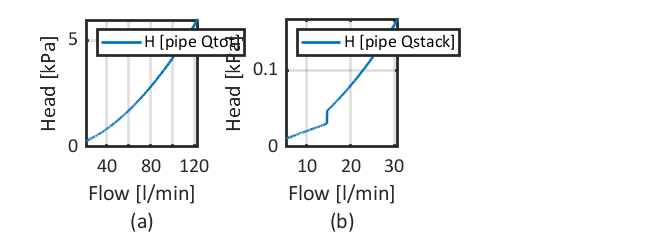

PipeAnalysis = figure();
tiledlayout(1,3,'TileSpacing','Compact');

nexttile(1)
plot(flow.tot,head.pipe_tot* 10^(-3), 'LineWidth', 2)
grid on
legend({'H [pipe Qtot]'},'location','northwest')
%title('Preassure drop in pipe', 'FontSize',12)
xlabel( {'Flow [l/min]'; '(a)'}, 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
xlim([min(flow.tot) max(flow.tot)])
ylim([0 max(head.pipe_tot* 10^(-3))])

nexttile(2)
plot(flow.stack,head.pipe_stack* 10^(-3), 'LineWidth', 2)
grid on
legend({'H [pipe Qstack]'},'location','northwest')
%title('Preassure drop in stack pipe', 'FontSize',12)
xlabel( {'Flow [l/min]'; '(b)'}, 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
xlim([min(flow.stack) max(flow.stack)])
ylim([0 max(head.pipe_stack* 10^(-3))])


changeFig(PipeAnalysis, 'PipeAnalysis', 2);

### Plot pressure pressure drop in pipe system vs flow

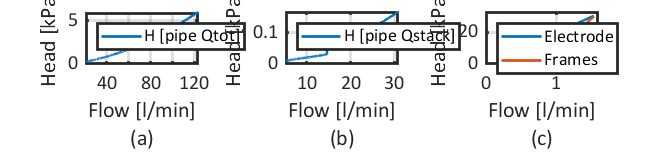

PressureDropAnalysis = figure();
tiledlayout(1,3,'TileSpacing','Compact');

nexttile(1)
plot(flow.tot,head.pipe_tot* 10^(-3), 'LineWidth', 2)
grid on
legend({'H [pipe Qtot]'},'location','northwest')
%title('Preassure drop in pipe', 'FontSize',12)
xlabel( {'Flow [l/min]'; '(a)'}, 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
xlim([min(flow.tot) max(flow.tot)])
ylim([0 max(head.pipe_tot* 10^(-3))])

nexttile(2)
plot(flow.stack,head.pipe_stack* 10^(-3), 'LineWidth', 2)
grid on
legend({'H [pipe Qstack]'},'location','northwest')
%title('Preassure drop in stack pipe', 'FontSize',12)
xlabel( {'Flow [l/min]'; '(b)'}, 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
xlim([min(flow.stack) max(flow.stack)])
ylim([0 max(head.pipe_stack* 10^(-3))])

nexttile(3)
plot(flow.cell,head.Electrode* 10^(-3), 'LineWidth', 2)
grid on
hold on
%plot(flow.cell,head.Gravity* 10^(-3), 'LineWidth',2)
plot(flow.cell, 2.*head.Frames* 10^(-3), 'LineWidth', 2)
hold off
legend({'Electrode','Frames'},'location','northwest')
%title('Pressure drop in single cell')
xlabel({'Flow [l/min]'; '(c)'})
ylabel('Head [kPa]')
xlim([0 1.6])
ylim([0 33])

changeFig(PressureDropAnalysis, 'PipeAnalysis', 3);

#### ANÁLISIS

**FF= 2** La figura (a) representa la pérdida de presión en las tuberías por donde circula el caudal total de la instalación, se observa que, el flujo presenta un comportamiento laminar hasta cierto valor de caudal, donde el flujo pasa a ser turbulento. En cambio, en la figura (b) se representa el comportamiento por los canales donde circula el caudal del stack, pudiendo observarse que para todo rango de caudales, el flujo tiene un copmortamiento laminar.

**FF= 3** Ambas figuras presentan que el comportamiento del flujo es laminar hasta cierto valor, para posteroirmente pasar a comportarse de manera turbulenta

**FF = 4-6** La figura (a) representa la pérdida de presión en las tuberías por donde circula el caudal total de la instalación, se observa que, para todo rango de caudales, el flujo presenta un comportamiento turbulento. En cambio, en la figura (b) se representa el comportamiento por los canales donde circula el caudal del stack, pudiendo observarse que hasta cierto rango de caudales, el flujo tiene un copmortamiento laminar, pero a partir de dicho rango, presenta un comportamiento turbulento.

**Comertial elements**

- flow.stack     -     2 codos de radio largo + 2 válvulas una a la entrada y otra a la salida del stack + 2T

- flow.tot         -     2 codos +  5 codos de radio largo + 2 kValve3Way

## Global evaluation of the hydraulic system

The battery is an open loop hydraulic system, where all of the fluid starts at the reservoir (tanks) and is returned to the reservoir, that implies that **Hf - Hi = 0.**

**Hf - Hi  = hPump - hStack - hPipe**

Then**:**

**hPump = hStack + hpipe**

head.PUMP = (head.STACK + head.PIPE) * 10^(-3); % kPa

## Equation of the hydraulic system:

    ecuInstalation = polyfit (flow.tot, head.PUMP,2); % (head - kPa) (flow - l/min)
    
    %flow.totSI = nStack .* flow.stack ./ 1000 .*60    % (m^3/h)
    ecuInstalationSI = polyfit (flow.tot.*60./1000, head.PUMP./9.81,2); % (head - mca) (flow - m^3/s)

    %   Valores de caudal y de altura
instalationValues = polyval (ecuInstalation, flow.tot);

### Plot pie minimum flow required / Pressure drop / Pie maximum flow required

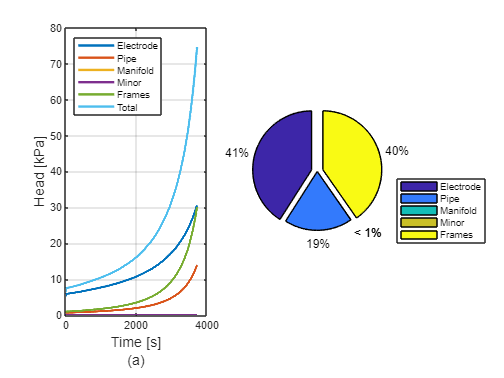

% Plot into first tile three times
headTimePie = figure();
t = tiledlayout(1,2,'TileSpacing','Compact');
% nexttile
% i = [min(head.Electrode) min(head.PIPE) min(head.Gravity) min(2.*head.Manifold) min(head.MinorLossesStack) min(2.*head.Frames) ];
% pie(i, [1 0 0 0 0 1])
% % Create legend
% lgd = legend({'Electrode','Pipe','Gravity','Manifold', 'Minor','Frames'},'location','bestoutside');
% title ('Losses for minimum flow required')

nexttile
plot(head.Electrode* 10^(-3), 'LineWidth', 2)
grid on
hold on
plot(head.PIPE* 10^(-3), 'LineWidth', 2)
%plot(2.*head.Gravity* 10^(-3), 'LineWidth', 2)
plot(2.*head.Manifold* 10^(-3), 'LineWidth', 2)
plot(head.MinorLossesStack* 10^(-3), 'LineWidth', 2)
plot(2.*head.Frames* 10^(-3), 'LineWidth', 2)
plot(head.PUMP, 'LineWidth', 2)
hold off
legend({'Electrode','Pipe','Manifold', 'Minor','Frames', 'Total'},'location','northwest')
%title('Pressure drop', 'FontSize',12)
xlabel({'Time [s]'; '(a)'}, 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
%xlim([0 max(flow.tot)])
%ylim([0 max(head.PUMP)])

nexttile
i = [max(head.Electrode) max(head.PIPE) max(2.*head.Manifold) max(head.MinorLossesStack) max(2.*head.Frames) ];
pie(i, [1 0 0 0 1])
% Create legend
lgd = legend({'Electrode','Pipe','Manifold', 'Minor','Frames'},'location','southeastoutside');

%title ('Losses for maximum flow required')
%changeFig(headTimePie, 'Head time pie',2);

### Plot pressure drop hydraulic system vs time

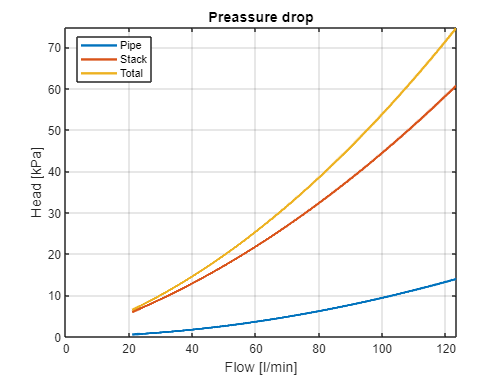

headBattery = figure();
plot(flow.tot,head.PIPE* 10^(-3), 'LineWidth', 2)
grid on
hold on
plot(flow.tot,head.STACK* 10^(-3), 'LineWidth', 2)
plot(flow.tot, head.PUMP, 'LineWidth', 2)

legend({'Pipe','Stack','Total'},'location','best')
title('Preassure drop', 'FontSize',12)
xlabel('Flow [l/min]', 'FontSize',12)
ylabel('Head [kPa]', 'FontSize',12)
xlim([0 max(flow.tot)])
ylim([0 max(head.PUMP)])
hold off

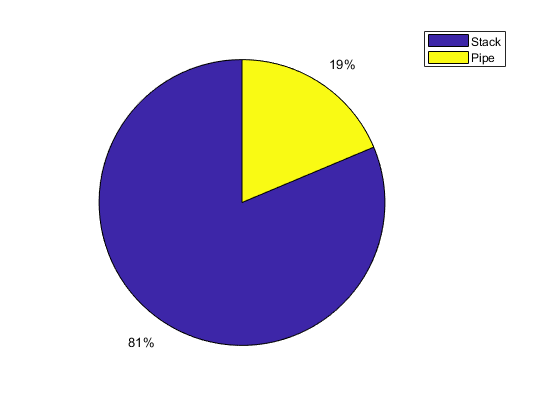

%changeFig(headBattery, 'headBattery', 1);
figure();
i = [max(head.Electrode+2.*head.Manifold+head.MinorLossesStack+ 2.*head.Frames) max(head.PIPE)];
pie(i)
% Create legend
lgd = legend({'Stack','Pipe'},'location','bestoutside');

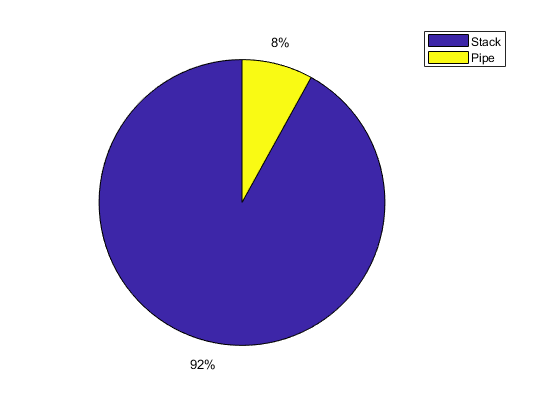

figure();
i = [min(head.Electrode+2.*head.Manifold+head.MinorLossesStack+ 2.*head.Frames) min(head.PIPE)];
pie(i)
% Create legend
lgd = legend({'Stack','Pipe'},'location','bestoutside');

### Plot pressure drop in single cell

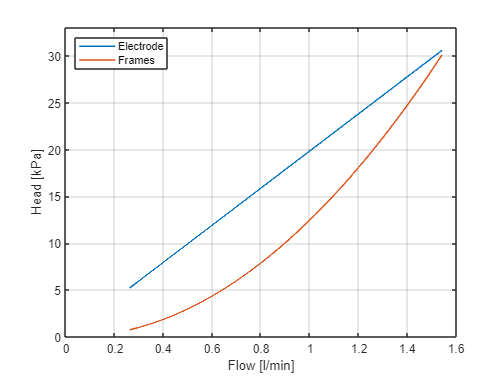

headCell = figure();
plot(flow.cell,head.Electrode* 10^(-3), 'LineWidth', 1.3)
grid on
hold on
%plot(flow.cell,head.Gravity* 10^(-3), 'LineWidth', 1.3)
plot(flow.cell, 2.*head.Frames* 10^(-3), 'LineWidth', 1.3)
hold off
legend({'Electrode','Frames'},'location','northwest')
%title('Pressure drop in single cell')
xlabel('Flow [l/min]')
ylabel('Head [kPa]')
xlim([0 1.6])
ylim([0 33])

%changeFig(headCell, 'headCell', 1);

Esta figura muestra las contribuciones de pérdidas para el máximo caudal requerido. 

En el electrodo es donde se produce mayor pérdida de presión, pero cuanto mayor es el FF, las contribuciones de pérdidas en los frames van aumentando, llegando al punto de superar las pérdidas de los electrodos debido a que si estos son cuadrados presentan unas pérdidas lineales con una pendiente aproximadamente de 45º y las pérdidas en los frames siguen una tendencia polinómica. Por lo que las curvas características de ambos elementos se pueden llegar a cruzar dependiendo del caudal requerido por la instalación.

# PUMPS

La validez de las bombas se ha limitado utilizando el punto de funcionamiento máximo, es decir, caudal y altura maxima que requiere nuestra operación, y un area con respecto a ese punto mayor %.

Se limíta el número de bombas posibles en la instalación porque, depende el caso, puede ser que colocando cierto número de bombas no se alcance el punto de operación requerido.

## Read information from the pumps and classified into valid and invalid 

pumps = readPumps; % Read pumps data 

for i = 1:length(pumps) % loop through the struct with the pumps datas
    % Operating point maximum
    pumps(i).maxOperatingPoint = intersectionPoint(pumps(i).eq, ecuInstalation);
    % Classification of the individual pumps into valid (1) and invalid (0)   
    pumps(i).efficiency = efficiency(pumps(i).ecuRdto,pumps(i).maxOperatingPoint);
    pumps(i).validLimit = validPumpLimit (pumps(i).maxOperatingPoint, flow.tot, instalationValues,limitPump.upper);
end

pumps

pumps = 1×14 struct array with fields:
    name
    eq
    R2
    ecuRdto
    Nref
    maxOperatingPoint
    efficiency
    validLimit



% for i=1:length(pumps)
%     a(i)=pumps(i).validLimit;
% end

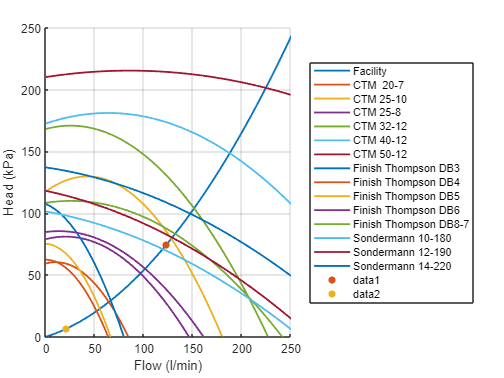

plotPumps = figure();
plotAllPossibilitiesPumps(ecuInstalation,pumps)
hold on
grid on
%scatter ([max(flow.tot) min(flow.tot)],[max(instalationValues);min(instalationValues)],'filled')
     scatter (max(flow.tot),max(instalationValues),'filled')
     scatter (min(flow.tot),min(instalationValues),'filled')
%title('Single Pump');
hold off
ylim([0 250])
xlim([0 250])

%changeFig(plotPumps, 'PumpsAllPossivilities', 1.5);

# Pump Power (W)

### Mix entre puntos homologos y variación de curvas

format short
pot = powerVariation(pumps, flow.tot, rto.Motor, rto.AFD, electrolite, ecuInstalation,battery.pHistoric)

pot = 1×5 struct array with fields:
    name
    maxOP
    Nref
    nRate
    nPrima
    nRdto
    powerImpeller
    powerReal
    efficiency


### Variación de curvas

pot2 = powerVariationSingleCurve(pumps, flow.tot, rto.Motor, rto.AFD, electrolite, ecuInstalation,battery.pHistoric)

pot2 = 1×5 struct array with fields:
    name
    eqOrigin
    Nref
    nRate
    nPrima
    nPrimaHz
    nRdto
    pImpeller
    powerReal
    pPump
    pMotor
    pVariador
    pHydraulicSystem
    efficiency
    energyEfficiency


% for i=1:length(pot2)
%     %a1=pot2(i).pHydraulicSystem;
%     b(i,1)=min(pot2(i).nPrima);
%     b(i,2)=max(pot2(i).nPrima);
%     b(i,3)=min(pot2(i).nPrimaHz);
%     b(i,4)=max(pot2(i).nPrimaHz);
%     b(i,5)=min(pot2(i).nRate);
%     b(i,6)=max(pot2(i).nRate);
% 
% 
%     b(i,7)=min(pot2(i).powerReal);
%     b(i,8)=max(pot2(i).powerReal);
%     b(i,9)=min(pot2(i).pHydraulicSystem);
%     b(i,10)=max(pot2(i).pHydraulicSystem);
%     b(i,11)=min(pot2(i).efficiency);
%     b(i,12)=max(pot2(i).efficiency);    
%     b(i,13)=min(pot2(i).energyEfficiency)*100;
%     b(i,14)=max(pot2(i).energyEfficiency)*100; 
% end
% b

### Puntos homologos únicamente

pot3 = powerVariationHomologos(pumps, flow.tot, rto.Motor, rto.AFD, electrolite, ecuInstalation,battery.pHistoric)

pot3 = 1×5 struct array with fields:
    name
    maxOP
    Nref
    efficiency
    nRate
    nPrima
    nPrimaHz
    nRdto
    powerImpeller
    powerReal


***EXTRACCIÓN DE DATOS BORRAR LUEGO***

% diferenciaRPM= pot2(1).nPrima-pot3(1).nPrima
% pot2.nRate
% pot3.nRate
% pot2.nPrima

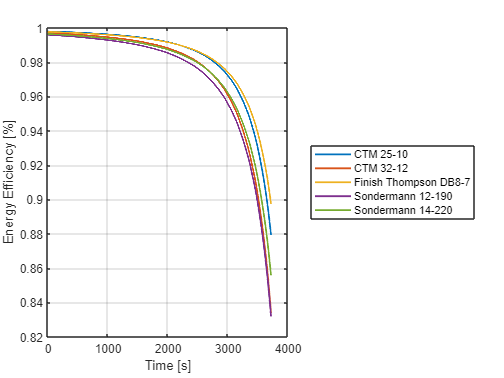

energyEFFIIENCY = figure();
plot(pot2(1).energyEfficiency, 'LineWidth', 1.5) 
hold on
grid on
plot(pot2(2).energyEfficiency, 'LineWidth', 1.5)
plot(pot2(3).energyEfficiency, 'LineWidth', 1.5) 
plot(pot2(4).energyEfficiency, 'LineWidth', 1.5) 
plot(pot2(5).energyEfficiency, 'LineWidth', 1.5) 
hold off
ylabel('Energy Efficiency [%]')
xlabel('Time [s]')
legend({'CTM 25-10','CTM 32-12','Finish Thompson DB8-7','Sondermann 12-190','Sondermann 14-220'},'location','eastoutside')

%changeFig(energyEFFIIENCY, 'EnergyEfficiency', 1.5);

# Speed rate plot

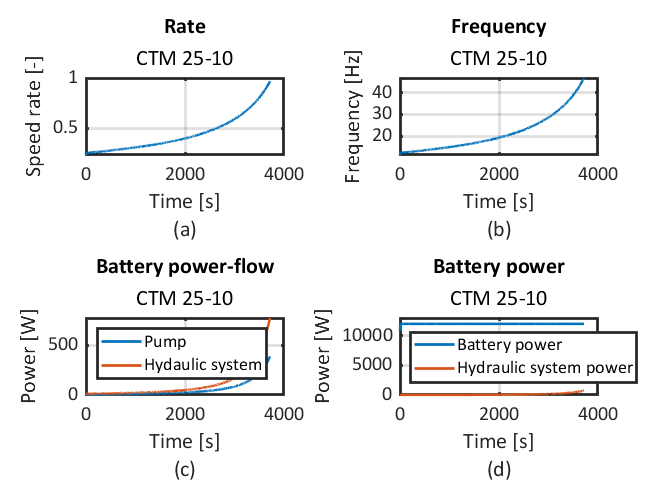

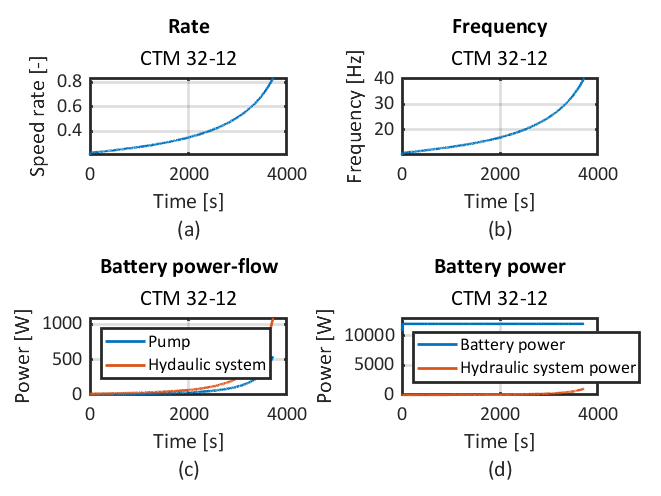

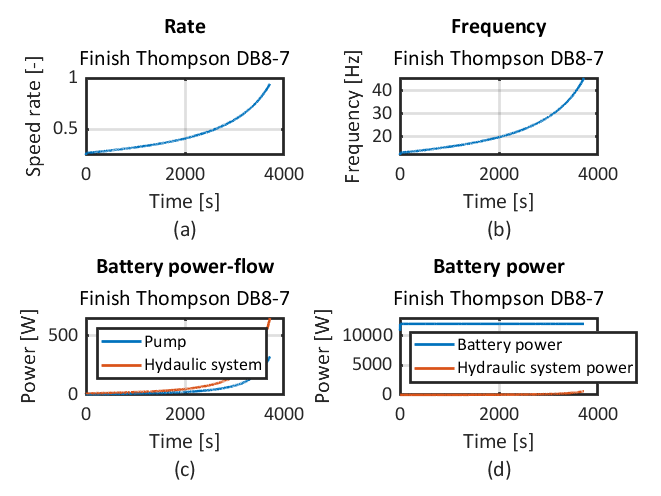

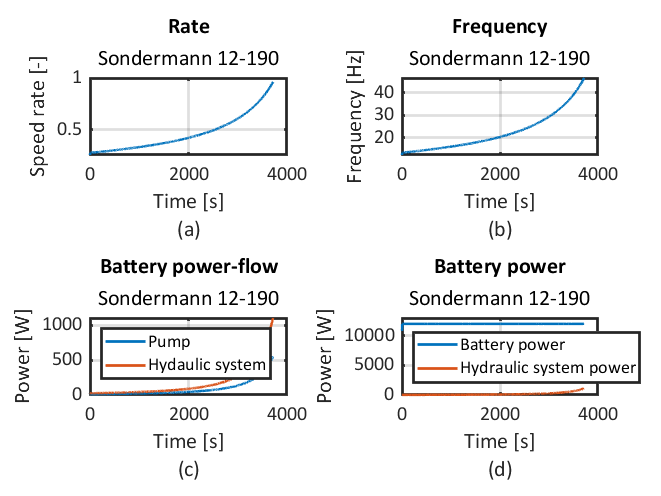

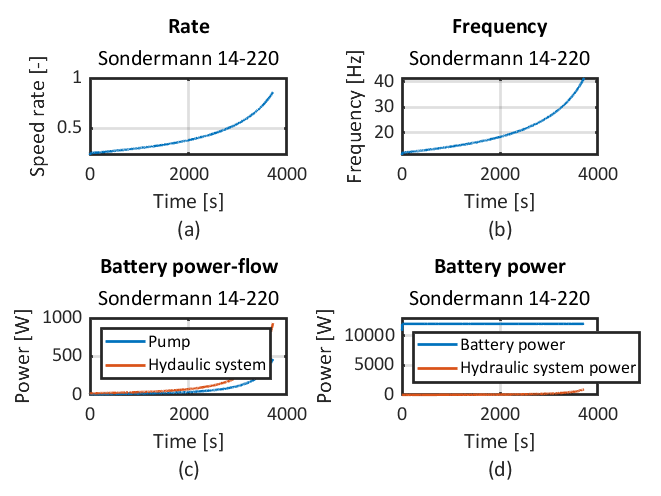

plotSpeedRate(pot,pot2,pot3,flow, battery)

% Arate=pot2(1).nRate-pot3(1).nRate
% max(pot2(1).nRate)
% min(pot2(1).nRate)
% max(pot2(1).nPrima)
% min(pot2(1).nPrima)
% max(pot2(1).nPrimaHz)
% min(pot2(1).nPrimaHz)
% Arpm=pot2(1).nPrima-pot3(1).nPrima
% Afrecuencia=pot2(1).nPrimaHz-pot3(1).nPrimaHz
% Apotencia=pot2(1).powerReal-pot3(1).powerReal
% max(pot2(1).powerReal)
% max(pot3(1).powerReal)
% min(pot2(1).powerReal)
% min(pot3(1).powerReal)

La variación de revoluciones siguiendo el modelo de puntos homologos presenta una variación de revoluciones considerable

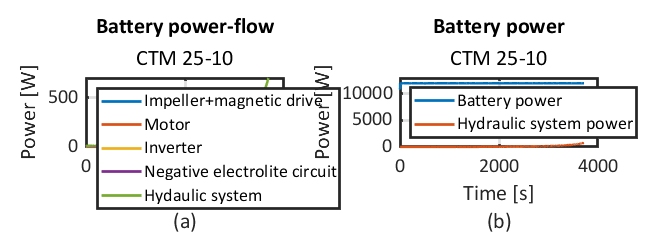

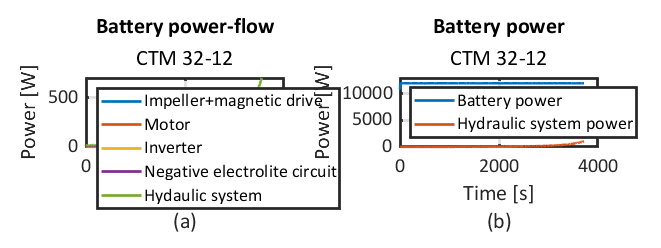

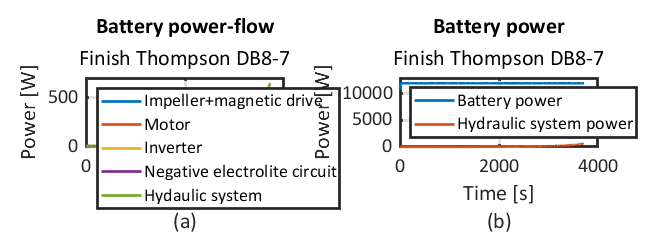

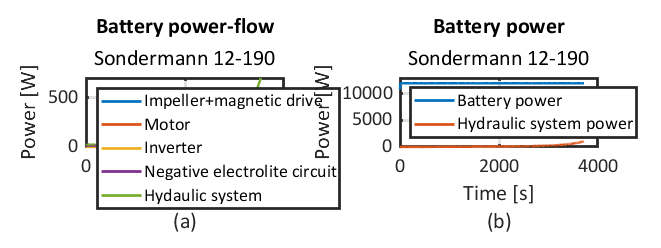

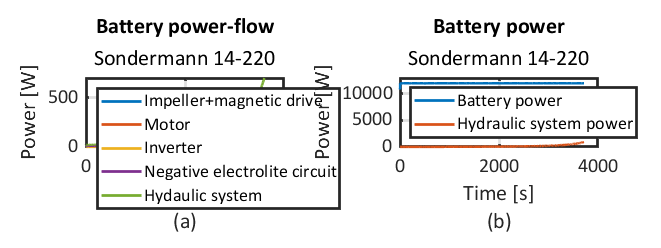

plotPowerPump(pot2,battery,flow,head)

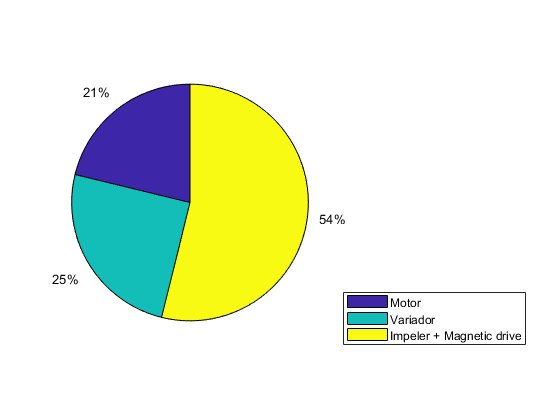

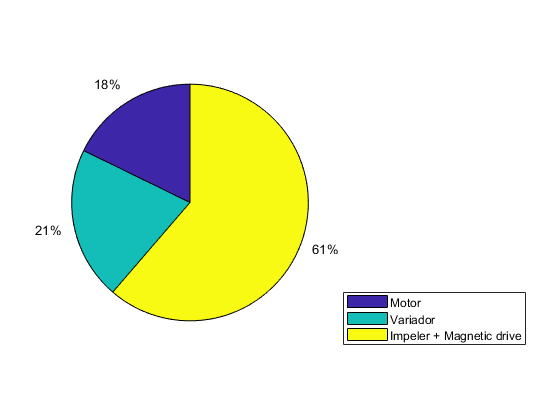

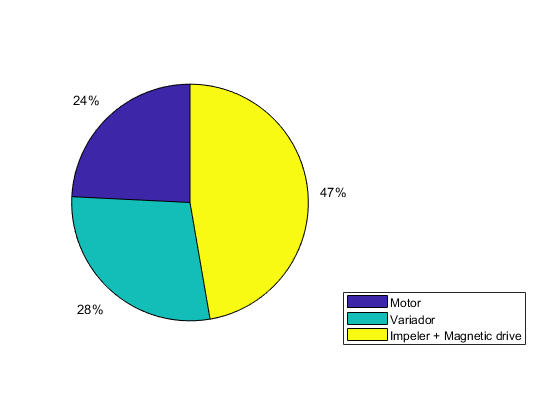

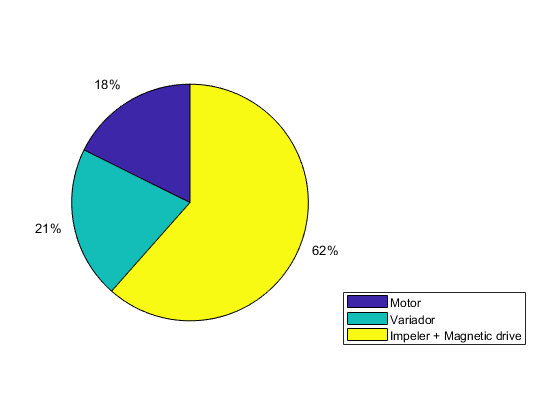

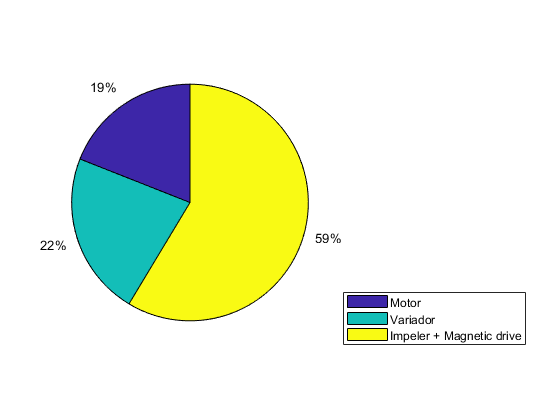

for i = 1: length (pot2) 
    figure()
i = [max(pot2(i).pMotor) max(pot2(i).pVariador) max(pot2(i).pPump) ];
    pie(i)
    % Create legend
    legend({'Motor','Variador','Impeler + Magnetic drive'},'location','southeastoutside');

end        

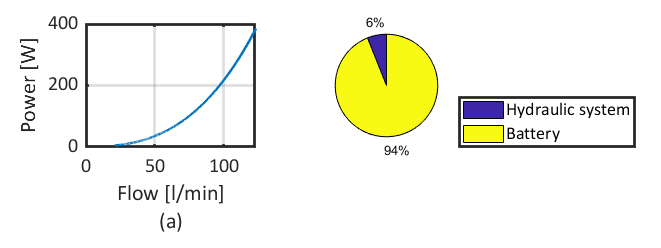

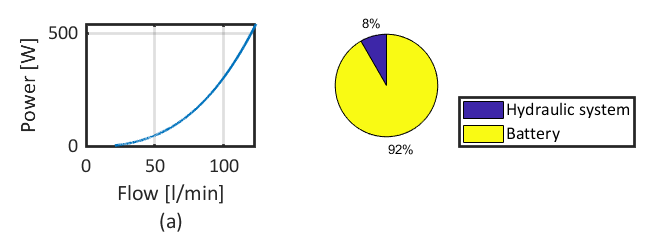

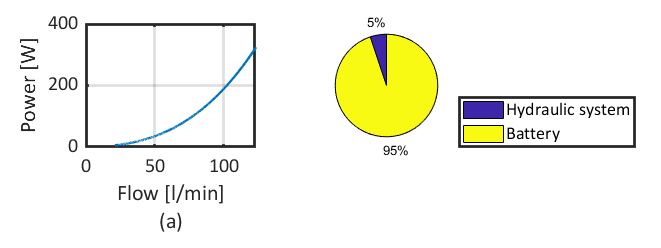

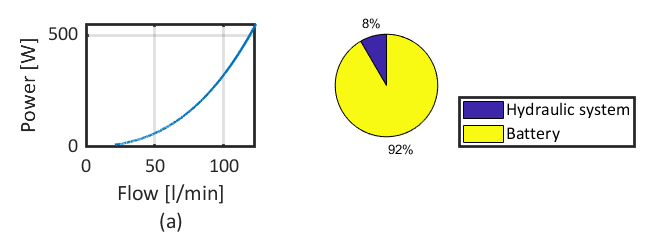

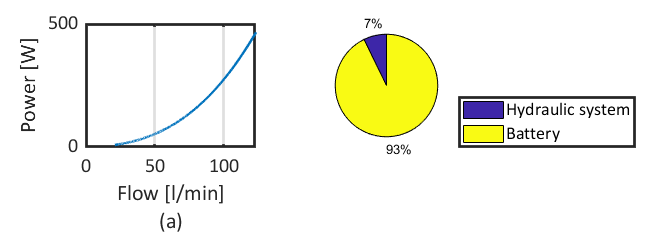

for i = 1: length (pot2)
    efficiency = figure();
    tiledlayout(1,2,'TileSpacing','Compact');

    nexttile(1)
        plot(flow.tot, pot2(i).powerReal, 'LineWidth', 2)
        ylabel('Power [W]')
        grid on
        %title('Battery power-flow',dataPower(i).name)
        xlabel({'Flow [l/min]'; '(a)'})

    nexttile (2)
    i = [max(pot2(i).pHydraulicSystem) max(abs(battery.pHistoric)) ];
    pie(i)
    % Create legend
    legend({'Hydraulic system','Battery'},'location','southeastoutside');
    % Create legend

    changeFig(efficiency, 'Efficiency',2);
end